# Leman FENG

## Question 4.1

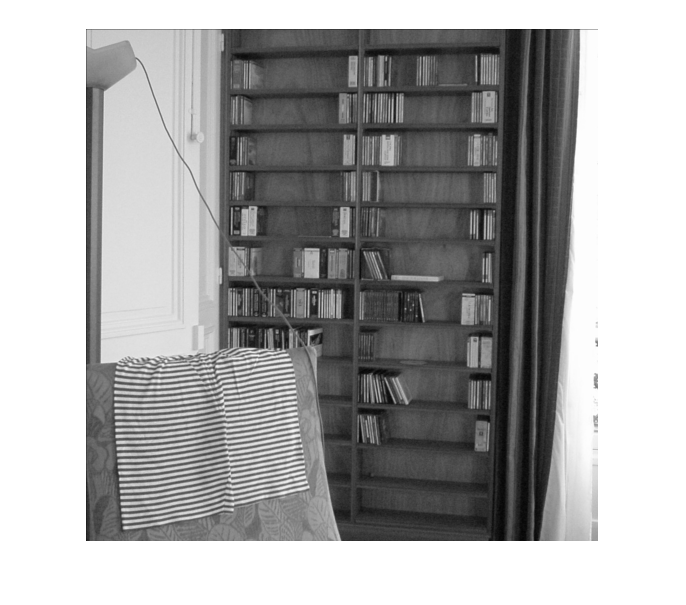

u = double(imread('room.pgm'))/255;
imshow(u);

## the following code samples the image 

## then make each pixel lambda times larger

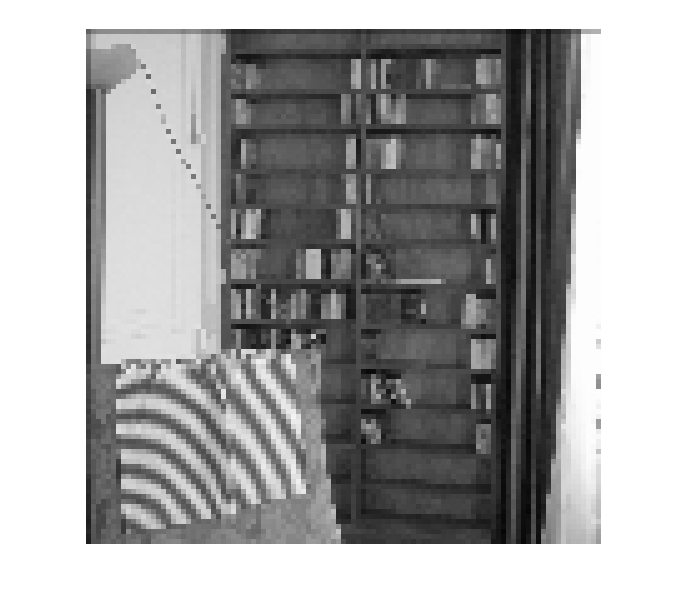

lambda =5;
v = u(1:lambda:end,1:lambda:end);
w = kron(v,ones(lambda));
[ny,nx] = size(u);
imshow(w);

## Question 4.2

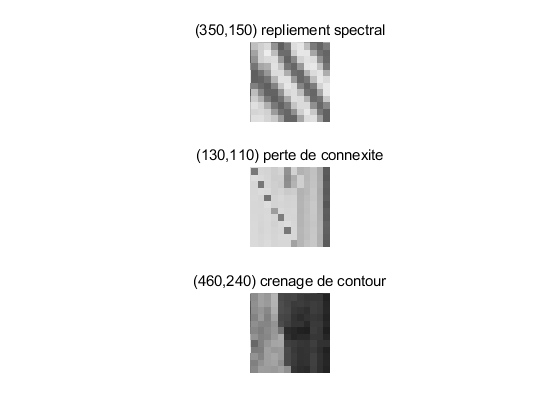

figure;
subplot(3,1,1);
imshow(w(340:400,140:200));
title("(350,150) repliement spectral");
subplot(3,1,2);
imshow(w(100:160,80:140));
title("(130,110) perte de connexite");
subplot(3,1,3);
imshow(w(420:480,220:280));
title("(460,240) crenage de contour");

## Question 4.3

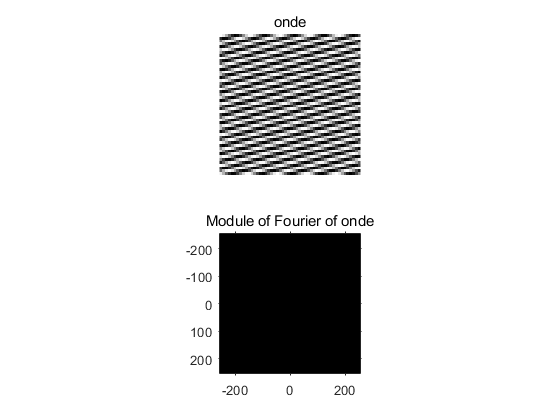

f = zeros(512);
f(190,50) = 2;
onde = real(ifft2(f));%+0.01;
figure;
subplot(211);
imshow(onde(1:50,1:50),[]);
title('onde')
F_onde = abs(fftshift(fft2(onde)));
a=-256;b=255;
subplot(212);
imshow(F_onde,[],'xdata',a:b,'ydata',a:b);
axis on;
title('Module of Fourier of onde');


[~,pos]=max(F_onde(:));
[x,y] = ind2sub(size(F_onde),pos);
x = (x-a)/(b-a);
y = (y-a)/(b-a);
fprintf('One peak of F(wave) is at [%2f,%2f]',x-1,y-1);

One peak of F(wave) is at [-0.365949,-0.091977]

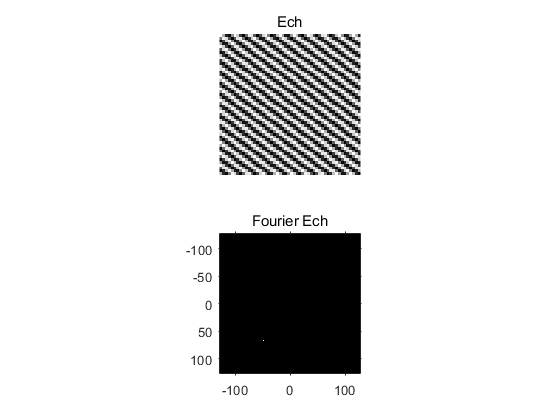


ech = onde(1:2:end,1:2:end);
figure;
subplot(211);
imshow(ech(1:50,1:50),[]);
title('Ech');

subplot(212);
F_ech = abs(fftshift(fft2(ech)));
a=-128;b=127;
imshow(F_ech,[],'xdata',a:b,'ydata',a:b);
axis on;
title('Fourier Ech');


F_ech = ifftshift(F_ech);
[~,pos]=max(F_ech(:));
[x,y] = ind2sub(size(F_ech),pos);
x = (x-a)/(b-a);
y = (y-a)/(b-a);
fprintf('One peak of F(resampled wave) is at [%2f,%2f]',x-1,y-1);

One peak of F(resampled wave) is at [0.247059,-0.301961]

After resampling, Dirac in Fourier changes, wave direction changes. Because resampling correspond to shrink support in frequency domain, Two Dirac will come back in another direction because of periodisation.

## Question 5.1

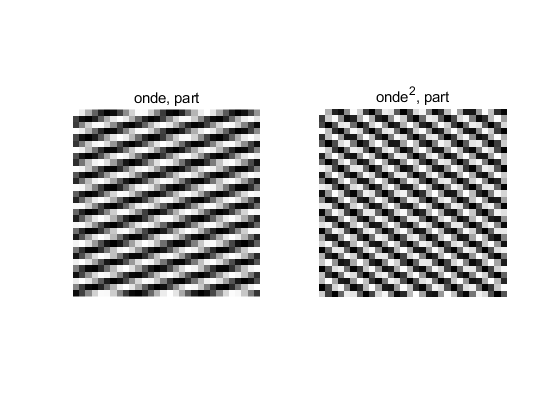

f = zeros(512);
x0=170;y0=50;
f(x0,y0) = 2;
f(512+2-x0,512+2-y0) = 2;
onde = (ifft2(f));
figure;
subplot(1,2,1);
imshow(onde(1:30,1:30),[]);
title('onde, part')
subplot(1,2,2);
onde2 = onde.^2;
imshow(onde2(1:30,1:30),[]);
title('onde^2, part')

The direction of wave changes when squared.

Because we have:


$$\widehat{f \cdot f} = \hat{f} * \hat{f}$$


Fourier of a square a function is the convolution of its Fourier.

Fourier of a high frequency pure wave is two symmetric Dirac functions. Convolution of these two Dirac to itself will generate three Dirac functions, one at center, two other is two times farther than before, which is outside the support. These two dirac will come back from another direction, so we see pure wave in another direction in onde^2

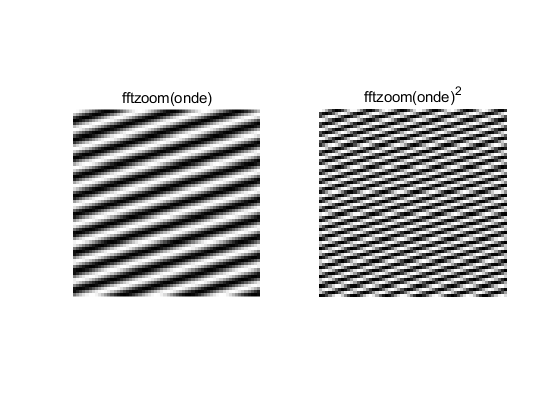

% Exo 5 Question 2
onde_zoom = fftzoom(onde,2);
figure;
subplot(1,2,1);
% imshow(onde(1:30,1:30),[]);
% title('onde')
imshow(onde_zoom(1:60,1:60),[]);
title('fftzoom(onde)');
onde_zoom2 = onde_zoom.^2;
subplot(1,2,2);
imshow(onde_zoom2(1:60,1:60),[]);
title('fftzoom(onde)^2');

This time function support is extended twice as large as before. So those two far away Dirac in 5.1 will still stay in support. That's why we didn't see change of direction this time.

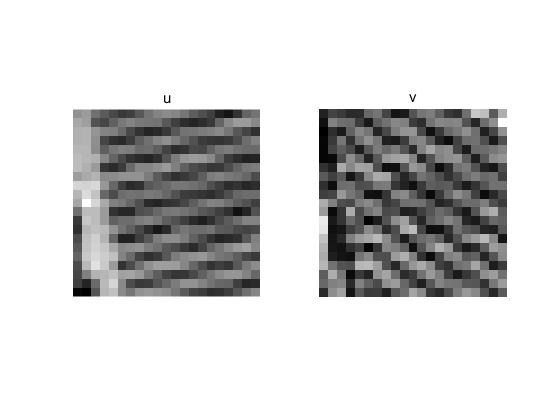

% Exo 5 Question 3
u = double(imread('nimes.pgm'))/255;
v = gradn(u);
figure;
subplot(1,2,1);
imshow(u(220:240,270:290),[]);
title('u');
subplot(1,2,2);
imshow(v(220:240,270:290),[]);
title('v');

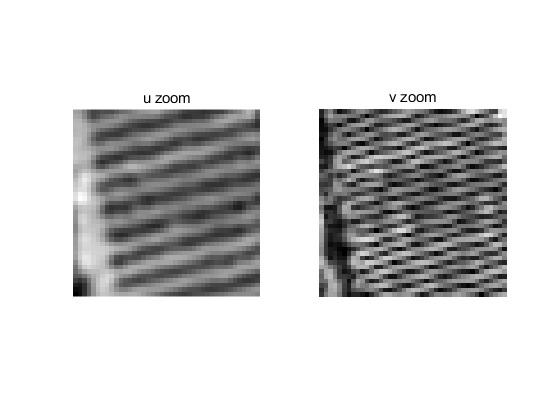


u_zoom = fftzoom(u,2);
v_zoom = gradn(u_zoom);

figure;
subplot(1,2,1);
imshow(u_zoom(440:480,540:580),[]);
title('u zoom');
subplot(1,2,2);
imshow(v_zoom(440:480,540:580),[]);
title('v zoom');

Take norm of gradient of a pure wave is like taking square of a pure wave. So we have same problem as 5.1 if the frequency is too high. We can see the gradient norm is in another direction. Using fftzoom in 5.2 can get better gradient norm.